## peaks01

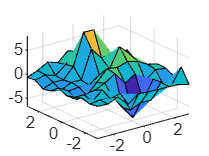

pointNum = 10;
[xx, yy, zz] = peaks(pointNum);
zz = zz + randn(size(zz)); % 加入雜訊

surf(xx, yy, zz);
axis tight

## peaks02

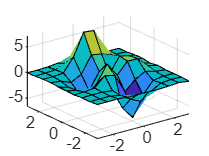

pointNum = 10;
[xx, yy, zz] = peaks(pointNum);
zz = zz + randn(size(zz)) / 10; % 加入雜訊

surf(xx, yy, zz);
axis tight


x = xx(:); % 轉為行向量
y = yy(:); % 轉為行向量
z = zz(:); % 轉為行向量
A = [(1 - x).^2 .*exp(-(x .^2) - (y + 1) .^2), (x / 5-x .^3-y.^5).*exp(-x.^2 - y.^2), exp(-(x+1).^2 - y.^2)];
theta = A \ z % 最佳的 theta 值

theta =     3.0580
  -10.0138
   -0.4431


## peaks03

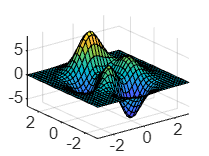

% pointNum = 10;
% [xx, yy, zz] = peaks(pointNum);
% zz = zz + randn(size(zz)) / 10; % 加入雜訊
% 
% x = xx(:); % 轉為行向量
% y = yy(:); % 轉為行向量
% z = zz(:); % 轉為行向量
% A = [(1 - x).^2 .*exp(-(x .^2) - (y + 1) .^2), (x / 5-x .^3-y.^5).*exp(-x.^2 - y.^2), exp(-(x+1).^2 - y.^2)];
% theta = A \ z % 最佳的 theta 值

pointNum = 31;
[xx, yy] = meshgrid(linspace(-3, 3, pointNum), linspace(-3, 3, pointNum));

x = xx(:); % 轉為行向量
y = yy(:); % 轉為行向量

A = [(1 - x).^2 .*exp(-(x .^2) - (y + 1) .^2), (x / 5-x .^3-y.^5).*exp(-x.^2 - y.^2), exp(-(x+1).^2 - y.^2)];
zz = reshape(A * theta, pointNum, pointNum);
surf(xx, yy, zz);
axis tight